K = 4; M = 2;Rc = 100;

f_list = 19.2:0.4:21.6;
bw = 21.6 - 19.2;
valratio = 0.2;
N_elements = 16;

% dataFolder = 'dataset/linear_CP_dataset/linear_CP_dataset_Y/';  % 你的数据目录
dataFolder = 'dataset/linear_CP_dataset/linear_CP_dataset_Y/';

X_set = [];
theta_set = [];
phi_set = [];
Y_set = [];
test_set = [];

% for i = 1:length(fileList)
%     load(fullfile(dataFolder, fileList(i).name));
sample_ratio = 2;
theta = -90:sample_ratio:90;
sample = 1:sample_ratio:181;
n = size(sample, 2);
real_ = 1:n; imag_ = n+1:2*n;

N_train = 150;N_test = 20;
for i = 130:130+N_train+N_test
    filename = sprintf( dataFolder + "Gn_%d", i);
    load(filename + ".mat");
    points = model_points{1};
    
    for f = 1:7
        ln_all = zeros(K*M +2 , N_elements);
        for j = 1:16
            ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc, 15, [Inf,Inf], 10, 120);
        end
%         X_set = [X_set; ln_all(1:M*K +2,:).'];
%         one_hot = zeros(size(f_list,2), N_elements);
%         one_hot(f, :) = 1;
%         X_set = [X_set; ln_all(1:M*K +2,:).', one_hot.'];
        X_set = [X_set; ln_all(1:M*K +2,:).', (f_list(f) - 20)/bw * ones(N_elements, 1)];
    
    
        Gn_theta = G_complex_all(sample, 1, f, :);
        Gn_phi = G_complex_all(sample, 2, f, :);
%         Gn = Gn_theta;
%         Gn = Gn_phi;
        Gn_theta = reshape(Gn_theta, [size(sample, 2) N_elements]);
        Gn_phi = reshape(Gn_phi, [size(sample, 2) N_elements]);
%         theta_set_complex = [theta_set_complex; Gn_theta.'];
%         phi_set_complex = [phi_set_complex; Gn_phi.'];
        Y_set = [Y_set; real(Gn_theta.'), imag(Gn_theta.'), real(Gn_phi.'), imag(Gn_phi.')];
    end
end

% theta_set = [real(theta_set_complex), imag(theta_set_complex)];
% phi_set = [real(phi_set_complex), imag(phi_set_complex)];
% Y_set = imag(Y_set);
% Y_set = angle(Y_set);
cv = cvpartition(size(X_set, 1), 'HoldOut', valratio);  

% 获取训练和测试索引
idxTrain = training(cv);
idxTest = test(cv);

N_sample = N_train*16*7;
idxTrain = 1:N_sample;
idxTest = N_sample+1:(N_train + N_test)*16*7;
% 提取训练集和测试集
XTrain = X_set(idxTrain, : );
YTrain = Y_set(idxTrain, :);

XValidation = X_set(idxTest, :);
YValidation = Y_set(idxTest, :);


% theta_set = theta_set(idxTrain,:);
% phi_set = phi_set(idxTrain,:);
% test_set = [X_set(idxTest)];
save_path = 'python_file\dataset.mat';
save(save_path, 'XTrain', 'YTrain', 'XValidation', 'YValidation');

% writematrix([XTrain, YTrain], "dataset/train_dataset.csv");
% writematrix([XValidation, YValidation], "dataset/test_dataset.csv");

for j = 1:16
    ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc, 15, [Inf,Inf], 100, 10);
end

% basis function -- theta
[AAA,idx] = sort(model_points{1}(:,1));
Gn_theta = G_complex_all(sample, 1, f, :);
Gn = reshape(Gn_theta, [size(sample, 2) N_elements]).';

idx_index = [1:5, 11:16];
basis_function = [Gn(idx(idx_index), :)];
i = 8;
alpha = basis_function.' \ Gn(idx(i), :).';
pre = basis_function.' * alpha;
figure; hold on;
plot(real(Gn(idx(i), :)));
plot(real(pre));

% transfer to multifrequence
theta_ = -90:2:90;phi_start = 0;
u_ = sind(theta_).' * cosd(phi_start);
v_ = sind(theta_).' * sind(phi_start);
angles_uv = [u_(:), v_(:)];

cn_set = [];
basis_cn = [];
basis_function = [];
Gn_set = [];
for f = 1:7
    for i = 1:100
        filename = sprintf( dataFolder + "Gn_%d", i);
        load(filename + ".mat");
        Gn_theta = G_complex_all(sample, 1, f, :);
        Gn_phi = G_complex_all(sample, 2, f, :);
    %     Gn = 1/sqrt(2) * (Gn_theta + 1j*Gn_phi);
        Gn = Gn_theta;
        Gn = reshape(Gn, [size(sample, 2) N_elements]);
        Gn_set = [Gn_set, Gn];
    end
    g_ave_complex = mean(Gn_set, 2);
    basis_function(:, f) = g_ave_complex;

    filename = sprintf( dataFolder + "Gn_1");
    load(filename + ".mat");

    Gn_theta = G_complex_all(sample, 1, f, :);
    Gn_phi = G_complex_all(sample, 2, f, :);
%     Gn = 1/sqrt(2) * (Gn_theta + 1j*Gn_phi);
    Gn = Gn_theta;
    Gn = reshape(Gn, [size(sample, 2) N_elements]);
    for i = 1:size(Gn, 2)
        cn_set(i, :, f) = calculate_virtual_excitations(Gn(:,i), P, Q, d,angles_uv, basis_function(:, f)).';
    end
end
cn_set_complex = cn_set;


f0 = 7;
i = 6;f = 7;
P=1;Q=11;
d = 0.5*f_list(f)/f_list(f0);

filename = sprintf( dataFolder + "Gn_1");
load(filename + ".mat");
Gn_theta = G_complex_all(sample, 1, f, :);
Gn_phi = G_complex_all(sample, 2, f, :);
%     Gn = 1/sqrt(2) * (Gn_theta + 1j*Gn_phi);
Gn = Gn_theta;
Gn = reshape(Gn, [size(sample, 2) N_elements]);

predict_aep_complex = reconstruct_aep(cn_set_complex(i, :, f0).', P, Q, d, angles_uv, basis_function(:,f));
figure;hold on;
plot(real(predict_aep_complex));plot(real(G_complex_all(sample, 1, f, i)));
legend('pred', 'sim', 'Location','northoutside')

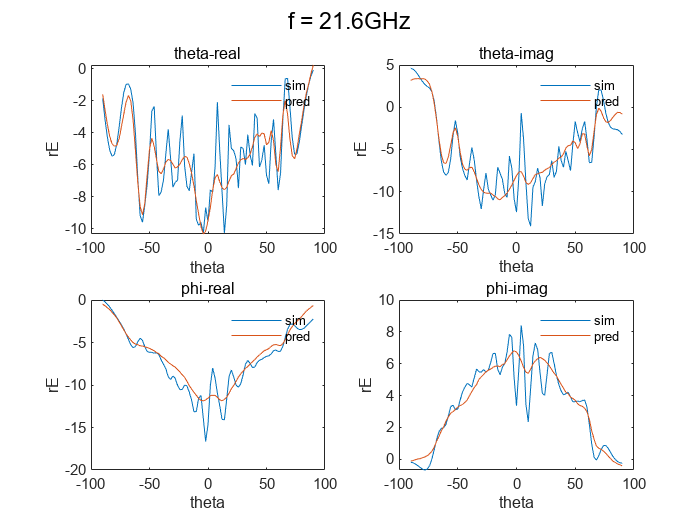

filename = sprintf(dataFolder + "Gn_130");
load(filename + ".mat");% array syhthesis
Gn = [];
% load('phi_preds.mat');YPred_phi = preds;
% load('theta_preds.mat');YPred_theta = preds;
f = 7;
real_ = 1:91;imag_ = 92:182;
load('preds.mat');
YPred_theta = preds(:, 1:182);
YPred_phi = preds(:, 183:364);

array_number = 1;
index = (f-1)*16 + 1:f*16;
% YPred_theta = predict(theta_model, X);
YPred_theta_complex = YPred_theta(:, real_) + 1j*YPred_theta(:, imag_);
YPred_theta_complex = YPred_theta_complex(index, :).';

% YPred_phi = predict(phi_model, X);
YPred_phi_complex = YPred_phi(:, real_) + 1j*YPred_phi(:, imag_);
YPred_phi_complex = YPred_phi_complex(index, :).';

k=1;
for i = 7
    figure;
    sgtitle(sprintf('f = %.1fGHz', f_list(f)));
    subplot(2,2,k);
    hold on;box on;
    plot(theta, real(G_complex_all(sample,1,f,i)));
    plot(theta, real(YPred_theta_complex(:,i)));
    xlabel('theta');
    ylabel('rE');
    title('theta-real')
    legend('sim', 'pred', 'box', 'off');
    k=k+1;
    
    subplot(2,2,k);
    hold on;box on;
    plot(theta, imag(G_complex_all(sample,1,f,i)));
    plot(theta, imag(YPred_theta_complex(:,i)));
    xlabel('theta');
    ylabel('rE');
    legend('sim', 'pred', 'box', 'off');
    title('theta-imag')
    k=k+1;
    
    subplot(2,2,k);
    hold on;box on;
    plot(theta, real(G_complex_all(sample,2,f,i)));
    plot(theta, real(YPred_phi_complex(:,i)));
    xlabel('theta');
    ylabel('rE');
    legend('sim', 'pred', 'box', 'off');
    title('phi-real');
    k=k+1;
    
    subplot(2,2,k);
    
    hold on;box on;
    plot(theta, imag(G_complex_all(sample,2,f,i)));
    plot(theta, imag(YPred_phi_complex(:,i)));
    xlabel('theta');
    ylabel('rE');
    legend('sim', 'pred', 'box', 'off');
    title('phi-imag');
    k=k+1;
    
end

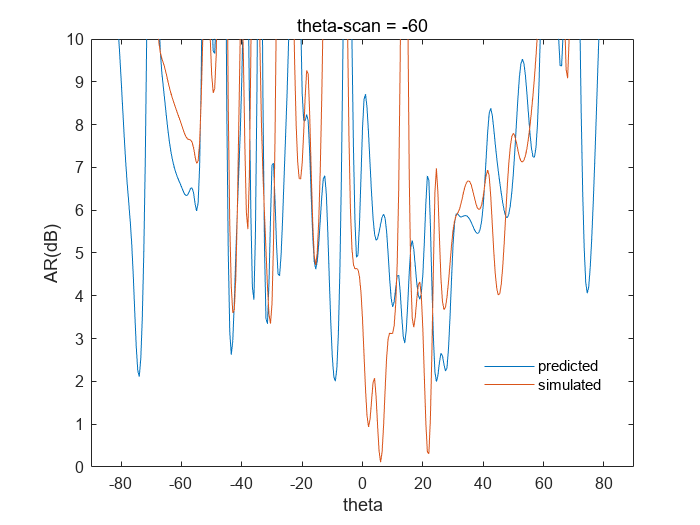

% validate data
theta_scandeg = -60;
phi_scandeg = 90;
u0 = [0,0,0];
u0(1) = sind(theta_scandeg) * cosd(phi_scandeg);
u0(2) = sind(theta_scandeg) * sind(phi_scandeg);

F = zeros(91,8);
theta_expect = -90:0.5:90;
N = 16;
points = model_points{1};
freq = f_list(f);
k0 = 2*pi * freq * 1e9 / 3e8;
for n = 1:N
    rn = [points(n,:)/1000,0];
    Gn(:,1) = YPred_theta_complex(:, n);
    Gn(:,2) = YPred_phi_complex(:, n);
    Gn(:,3) = 1/sqrt(2) * (YPred_theta_complex(:, n) + 1j*YPred_phi_complex(:,n));% 
    Gn(:,4) = 1/sqrt(2) * (YPred_theta_complex(:, n) - 1j*YPred_phi_complex(:,n));


    Gn(:,5) = G_complex_all(sample,1, f, n);
    Gn(:,6) = G_complex_all(sample,2, f, n);
    Gn(:,7) = 1/sqrt(2) * (G_complex_all(sample,1,f, n) + 1j*G_complex_all(sample,2,f,n));
    Gn(:,8) = 1/sqrt(2) * (G_complex_all(sample,1,f, n) - 1j*G_complex_all(sample,2,f,n));
%     Gn3 = gn_periodic;
    phase_n = k0 * (-dot(rn, u0));
    for i = 1:8
        F(:,i) = F(:,i) + Gn(:,i) .* exp(1j * k0 * (rn(2) * sind(theta.')) + 1j * phase_n);
    end
end
tao = angle(F(:,8) ./ F(:,7))/2;
Ex = F(:, 5) .* cos(tao) - F(:,6) .* sin(tao);
Ey = F(:, 5) .* sin(tao) + F(:,6) .* cos(tao);
AR = abs(Ey ./ Ex);
AR = interp1(theta,AR, theta_expect, 'spline');
idx = AR<1;
AR(idx) = 1 ./ AR(idx);

tao = angle(F(:,4) ./ F(:,3))/2;
Ex = F(:, 1) .* cos(tao) - F(:,2) .* sin(tao);
Ey = F(:, 1) .* sin(tao) + F(:,2) .* cos(tao);
AR_Pred = abs(Ey ./ Ex);
AR_Pred = interp1(theta,AR_Pred, theta_expect, 'spline');
idx = AR_Pred<1;
AR_Pred(idx) = 1 ./ AR_Pred(idx);


figure; box on;hold on;
plot(theta_expect, 20*log10(AR_Pred));
plot(theta_expect, 20*log10(AR));
title("theta-scan = " + num2str(theta_scandeg));
xlabel('theta');ylabel("AR(dB)");
xlim([-90 90]);ylim([0 10]);
legend('predicted','simulated','Location','best','box', 'off');

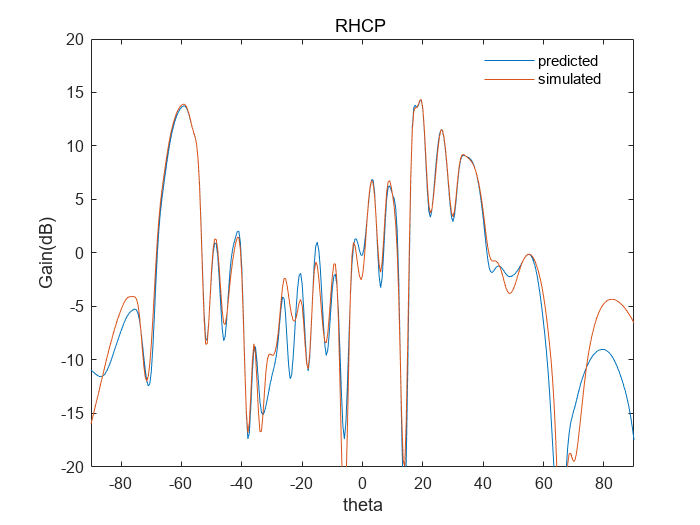


U = abs(F) .^2 /2 /377;
Gain = 4*pi*U/ N; 
Gain = 10 * log10(Gain);
Gain(isnan(Gain)) = -20;
% plot(theta, abs(F) - F_ref);
Gain = interp1(theta,Gain, theta_expect, 'spline');
figure;
hold on;box on;
plot(theta_expect, Gain(:,3));
plot(theta_expect, Gain(:,7));
% plot(-90:90, GainPlot1.dBRealizedGainRHCP, '--');
xlabel('theta');ylabel("Gain(dB)");
ylim([-20 20]);xlim([-90 90]);title('RHCP ');
legend("predicted", 'simulated','Location','best', 'box', 'off');

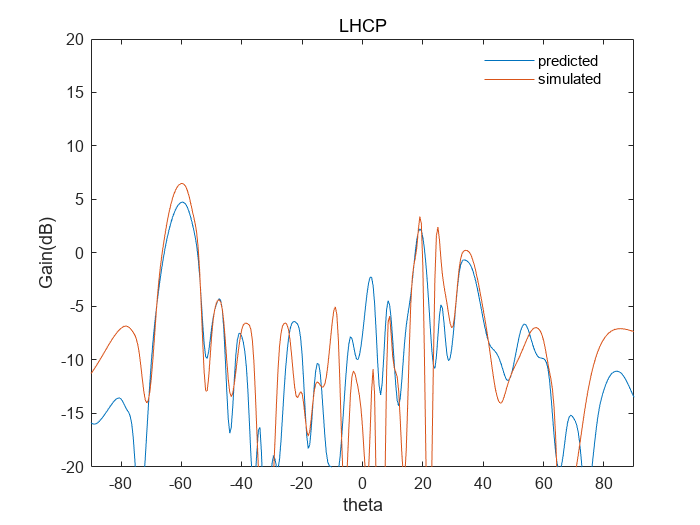


figure;
hold on;box on;
plot(theta_expect, Gain(:,4));
plot(theta_expect, Gain(:,8));
xlabel('theta');ylabel("Gain(dB)");
ylim([-20 20]);xlim([-90 90]);title("LHCP");
legend("predicted", 'simulated','Location','best', 'box', 'off');


% [AAA,idx] = sort(model_points{1}(:,1));
% figure;
% scatter(model_points{1}(:,1), model_points{1}(:,2));
% Y = [];X = [];
% f_index = 1;
% for f = f_index
%     ln_all = zeros(K*M +2 , N_elements);
%     for j = 1:16
%         ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc, 15, [Inf,Inf], 100, 10);
%     end
% %     X = [X; ln_all(1:M*K +2,:).', f_list(f) * ones(16,1)];
%     X = [X; ln_all(1:M*K +2,:).'];
%     
%     sample = 1:2:181;
% 
%     Gn_theta = G_complex_all(sample, 1, f, :);
%     Gn_phi = G_complex_all(sample, 2, f, :);
%     Gn = Gn_theta;
% %     Gn = Gn_phi;
%     Gn = reshape(Gn, [size(sample, 2) N_elements]);
%     Y = [Y; Gn.'];
% end
% YPred = YPred_theta_complex;
% k=1;
% i = 1;
% figure;
% for f = f_index
%     figure ;hold on;
%     plot(theta, real(YPred(:, i)));
%     plot(theta, real(Y(i, :)));
%     grid on;
%     xlabel('theta');ylabel('rE(V/m)');
%     hold off;   
%     k=k+1;
%     figure ;hold on;
%     plot(theta, imag(YPred(:, i)));
%     plot(theta, imag(Y(i, :)));
%     grid on;
%     xlabel('theta');ylabel('rE(V/m)');
%     hold off;   
%     k=k+1;
% end
% 
% legend('pred', 'sim','box','off','Location','best');
% 
% 
% lgraph = layerGraph;
% inputLayers = [
%     featureInputLayer(inputSize, 'Name', 'input')
%     fullyConnectedLayer(hiddenDim, 'Name', 'fc_initial', 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg) % Initial projection
%     reluLayer('Name','relu_initial')
%     ];
% lgraph = addLayers(lgraph, inputLayers);
% 
% % --- Create Residual Blocks ---
% currentLayerOutput = 'relu_initial'; % Output name of the initial layers
% 
% for i = 1:numResidualBlocks
%     blockName = sprintf('resBlock%d', i);
% 
%     % Layers within the residual block
%     blockLayers = [
%         fullyConnectedLayer(hiddenDim, 'Name', [blockName '_fc1'], 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg)
%         batchNormalizationLayer('Name', [blockName '_bn1'])
%         reluLayer('Name', [blockName '_relu1'])
%         dropoutLayer(dropoutProb, 'Name', [blockName '_drop1']) % Optional dropout
% 
%         fullyConnectedLayer(hiddenDim, 'Name', [blockName '_fc2'], 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg)
%         batchNormalizationLayer('Name', [blockName '_bn2'])
%         % Note: ReLU after addition
%     ];
%     lgraph = addLayers(lgraph, blockLayers);
% 
%     % Addition layer for the skip connection
%     addLayer = additionLayer(2, 'Name', [blockName '_add']); % Add two inputs
%     lgraph = addLayers(lgraph, addLayer);
% 
%     % Final ReLU for the block
%     finalReluLayer = reluLayer('Name', [blockName '_relu_final']);
%     lgraph = addLayers(lgraph, finalReluLayer);
% 
%     % --- Connect Layers within the block and the skip connection ---
%     % Connect main path within the block
%     lgraph = connectLayers(lgraph, currentLayerOutput, [blockName '_fc1']); % Input to block's first FC
%     lgraph = connectLayers(lgraph, [blockName '_bn2'], [blockName '_add/in1']); % Main path output to addition layer
% 
%     % Connect skip connection path
%     lgraph = connectLayers(lgraph, currentLayerOutput, [blockName '_add/in2']); % Block input to addition layer
% 
%     % Connect addition layer to final ReLU
%     lgraph = connectLayers(lgraph, [blockName '_add'], [blockName '_relu_final']);
% 
%     % Update the output name for the next iteration/block
%     currentLayerOutput = [blockName '_relu_final'];
% end
% 
% outputLayers = [
%     fullyConnectedLayer(outputSize, 'Name', 'fc_output', 'WeightL2Factor', l2Reg, 'BiasL2Factor', l2Reg) % Final FC layer to get 2 outputs
%     regressionLayer('Name', 'output') % Regression layer for training
%     ];
% lgraph = addLayers(lgraph, outputLayers);
% 
% % Connect the last residual block to the final output layer
% lgraph = connectLayers(lgraph, currentLayerOutput, 'fc_output');